# Drone Payload Structure Design and Analysis

In this project, you are optimizing drone arm design, including geometry and material selection, to maximize payload capacity while ensuring structural integrity under motor-induced loads. You will use MATLAB to perform force balance analysis and finite element modeling to quantitatively support your design solution.

Use this Live Script as a template to get started on your project solution. You may include helper functions at the bottom of this document or as separate files. For a tutorial on how to use Live Scripts, check out this [video](https://www.youtube.com/watch?v=hUXTyPYRidM).

**Suggested Tasks**

- Gather your starter assumptions and load the material properties into MATLAB.

- Propose at least two drone arm designs

- Perform a thrust-to-weight analysis to evaluate each of your designs across all material options. Your design must meet a minimum payload requirement and safety standards.

- Perform finite element analysis across all design and material options.

- Recommend a final design solution.

## Break Down the Problem

In the space below, define the problem statement:

List the requirements, constraints, and success criteria for the project:

- The drone (excluding arms) weighs 1 kg.

- The drone must support a minimum payload of 0.5 kg.

- The drone's thrust to weight ratio must be greater than 2.

- Designs should maximize payload capacity.

- Factor of safety should be greater than 2.

- Drone arms should be within a reasonable volume given the mass of the drone

- As a group we decided this was 20 cm x 2 cm x 2 cm (L x W x H)

- This was as later shrunk down to 12 cm x 2 cm x 2 cm during the design phase

- Drone arm models must be able to be made in real life, using methods such as 3D printing or injecting molding.

What is your proposed solution?

         The solution is to create a drone arm design that is capable of supporting the highest payload possible, while also being durable and withstanding the force of the motors.

List the steps you will need to take to achieve your proposed solution:

- Create sketches and initial CAD models.

- Perform a finite element analysis to find arm designs with the highest factor of safety while still being light weight.

- Perform a thrust to weight analysis to determine the maximum payload capacity.

What challenges did you face in the process of achieving the solution?

- The group lacked familiarity with MATLAB programming.

- The finite element analysis had lots of issues early on which required debugging.

- Half of the group quit the project, requiring more work to be done by less people.

## Task 1: Gather your starter assumptions and load material properties

Load the provided `droneArmMaterials.mat` file into MATLAB. This contains a data struct with the material properties for six different materials commonly used for drones (carbon fiber composite, aluminum alloy, fiberglass composite, PLA plastic, ABS plastic, and wood). For each material, you have been provided the following information:

- Density ($\rho$), in $\frac{\textrm{kg}}{m^3 }$

- Young's Modulus ($E$) in Pa

- Poisson's ratio ($\nu$), unitless

- Yield strength, in Pa

- Average cost per meter in US dollars

For this project, you can assume the following design parameters:

- Quadcopter drone with 4 motors and 4 propellers

- Each motor can provide up to 1kg thrust

- Acceleration due to gravity: $g=9\ldotp 81\;\frac{m}{s^2 }$ 

- Total weight of the drone components without the arms or the payload: 1kg 

The breakdown of the weight of each drone component is as follow:

- Battery = 0.3kg

- Each motor = 65g, 4 motors = 0.26kg

- Each propeller = 10g, 4 propellers = 0.04 kg

- Each electronic speed controller = 30g, 4 electronic speed controllers = 0.12 kg

- Flight controller and electronics = 0.05kg

- Receiver/GPS = 0.03kg

- Drone frame (center body) excluding arms = 0.2kg

% From EPPDronePayloadTeam7\FiniteElementAnalysisArmA.m
% Open relevant files
model = femodel(AnalysisType="structuralStatic", Geometry="DroneArmA.STL");
load("droneArmMaterials.mat");

% Constants
g = 9.81; % gravity in m/s^2
thrust = 1; % thrust in kg force
thrust = thrust*g; % Converted to Newtons
motorMass = 65; % in grams
propMass = 10; % in grams
weight = (motorMass + propMass)*g/1000; % Weight of the objects attached to the drone arm in Newtons

clear % frees up variables to continue running script, not included in code

## Task 2: Propose at least two drone arm designs

Develop at least two distinct drone arm designs by drawing clear, neatly labeled sketches that show key geometric features, including:

- Overall shape (e.g. beam, tube, truss structure)

- Dimensions (length, width, thickness)

- Motor mount location

- Where the arm connects to the drone body 

The two designs should be meaningfully different from each other (e.g. different geometries or structural strategies) and not just small variations of the same idea.

Navigate to the 'Insert' tab and insert pictures of your sketches in the space below (hand-drawn or digital). Include a short design description for each sketch that includes:

- Geometry (e.g. solid beam, hollow tube, beam with trusses)

- Why you chose this design

- How it might perform under load

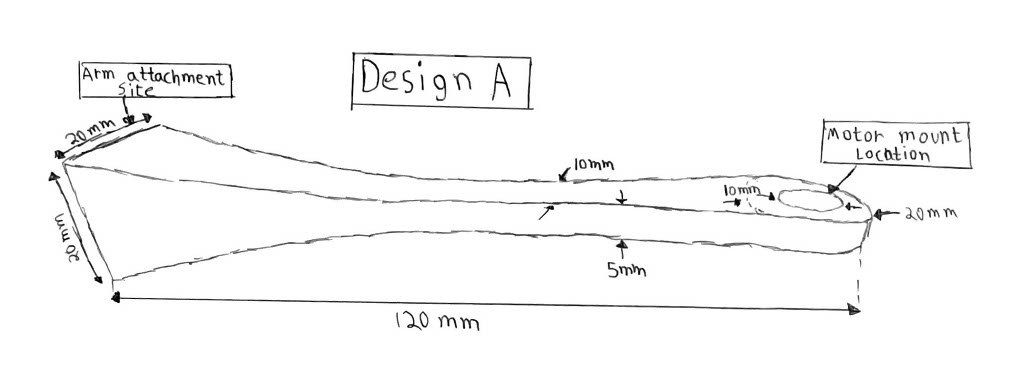

Drone Arm A is a solid beam that smoothly curves in order to minimize mass while having an acceptable factor of safety. This design was chosen due to a desire to make a simple arm design that could be manufactured in a more affordable manner. Most of the load should be near the center of mass, rather than close to the motor.

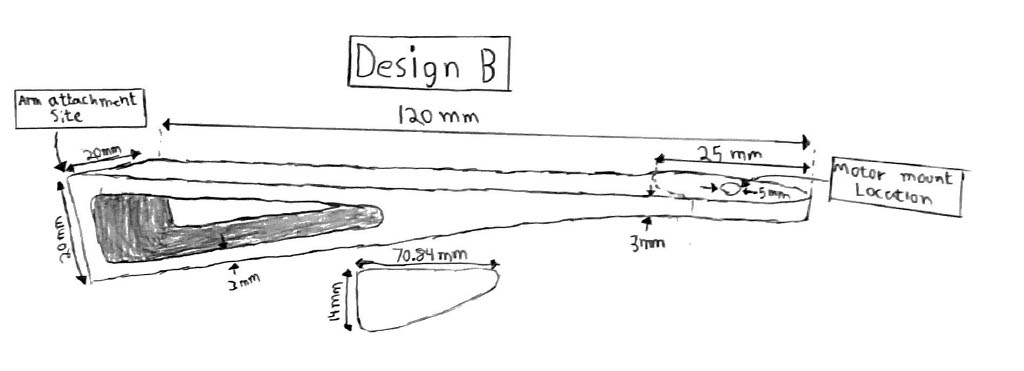

Drone Arm B is a triangular arm that uses a brace in order to heavily reinforce a rectangular beam. This design was chosen due to the structural reinforcement providing a rigid support for the length of the arm, while minimizing mass compared to using a thicker material. The load should be more evenly distributed throughout the arm.

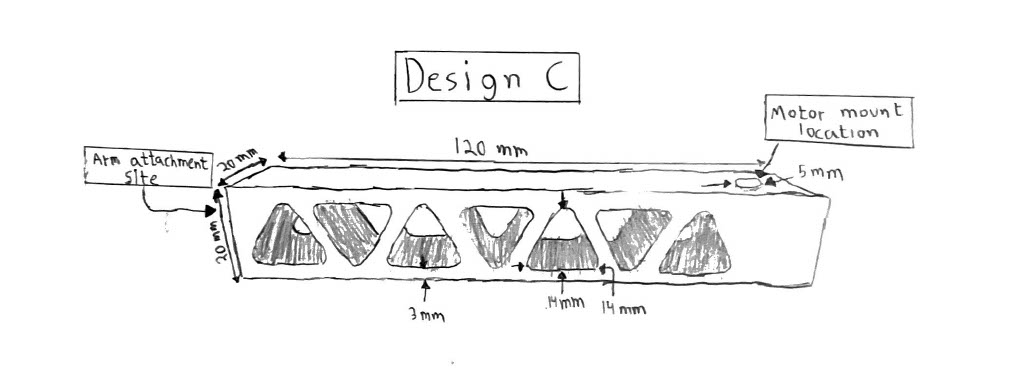

Drone Arm C is a truss that uses triangular cutouts to minimize mass while maximizing the strength of the arm. This design was chosen due to it providing significant strength compared to thinner arm designs, yet without a high value of mass. The load should be transferred through each of the truss segments into the sides of the arm.

## Task 3: Perform thrust-to-weight analysis across all design and material options

Write a MATLAB function that will perform a thrust-to-weight analysis across all design and material options. This analysis will help you evaluate which drone arm design and which material optimizes payload capacity while meeting suggested safety requirements. 

- Your design must support a minimum payload of 0.5kg. 

- Your design must meet a thrust-to-weight ratio of at least 2:1 to ensure safe and stable flight. This safety standard is widely used in drone design. Conceptually, it means that the drone's maximum thrust must be at least twice its weight. This ensures stable hovering and maneuvering with a safety margin. Note that the thrust-to-weight safety margin is a system-level safety standard for drone flight that is distinct from the structural safety factor of the drone arms (which you will evaluate later through finite element analysis).

- Your goal is calculate maximum payload capacity for each design and material option (i.e. what is the heaviest payload your drone design could carry while still allowing the drone to safely take off?)

Ensure that the results of your analysis can be readily interpreted, e.g. in the form of a summary table or plot.

Note: if you have two drone arm designs, the expected output should be 12 payload capacity estimates (2 designs across 6 materials options).

%%Thrust vs Weight analysis
load('droneArmMaterials.mat') %Load in materials data
%Design 1
fv=stlread('DroneArmA.stl'); %Creates triangulation of geometry
P1=fv.Points;
T1=fv.ConnectivityList;
vol1=0;
for i=1:size(T1,1)
    p1=P1(T1(i,1),:);
    p2=P1(T1(i,2),:);
    p3=P1(T1(i,3),:);
    vol1=vol1+dot(p1,cross(p2,p3))/6;
end
vol1=abs(vol1);
thrust_kg=1*4;%thrust in kg
t_to_w_ratio=2; %Defines required thrust to weight ratio
drone_body_mass=1; %Mass of all non-arm components of drone
max_mass=thrust_kg/t_to_w_ratio;%max mass capacity of drone+payload
density = [materials.rho_kg_m3]; %Extracts density of materials into an array
arm_mass= vol1*density; %Calculates mass of a single drone arm in kg
drone_mass=drone_body_mass+4*arm_mass; %Calculates mass of entire drone in kg
payload_capacity=max_mass-drone_mass; %Calculates payload capacity in kg
%Design 2
fv2=stlread('DroneArmB.stl'); %Creates triangulation of geometry
P2=fv2.Points;
T2=fv2.ConnectivityList;
vol2=0;
for i=1:size(T2,1)
    p1=P2(T2(i,1),:);
    p2=P2(T2(i,2),:);
    p3=P2(T2(i,3),:);
    vol2=vol2+dot(p1,cross(p2,p3))/6;
end
vol2=abs(vol2);
arm_mass2=vol2*density; %Calculates mass of a single drone arm in kg
drone_mass2=drone_body_mass+4*arm_mass2; %Calculates mass of entire drone in kg
payload_capacity2=max_mass-drone_mass2; %Calculates payload capacity in kg
%Design 3
fv3=stlread('DroneArmC.stl'); %Creates triangulation of geometry
P3=fv3.Points;
T3=fv3.ConnectivityList;
vol3=0;
for i=1:size(T3,1)
    p1=P3(T3(i,1),:);
    p2=P3(T3(i,2),:);
    p3=P3(T3(i,3),:);
    vol3=vol3+dot(p1,cross(p2,p3))/6;
end
vol3=abs(vol3);
arm_mass3=vol3*density; %Calculates mass of a single drone arm in kg
drone_mass3=drone_body_mass+4*arm_mass3; %Calculates mass of entire drone in kg
payload_capacity3=max_mass-drone_mass3; %Calculates payload capacity in kg

%%Tabulate
payloadTable = table( ...
    payload_capacity.', ...
    payload_capacity2.', ...
    payload_capacity3.', ...
    'VariableNames', {'Design_A','Design_B','Design_C'}, ...
    'RowNames', { ...
        'Carbon_Fiber_CFRP', ...
        'Aluminum_Alloy', ...
        'Fiberglass_GFRP', ...
        'PLA_Plastic', ...
        'ABS_Plastic', ...
        'Wood_Birch'});
fprintf('\n                              Payload Capacity (kg)\n\n')


                              Payload Capacity (kg)




disp(payloadTable)

                         Design_A    Design_B    Design_C
                         ________    ________    ________

    Carbon_Fiber_CFRP    0.91731      0.9104     0.81776 
    Aluminum_Alloy       0.86046      0.8488     0.69247 
    Fiberglass_GFRP      0.90181      0.8936     0.78359 
    PLA_Plastic           0.9354        0.93     0.85763 
    ABS_Plastic          0.94574      0.9412     0.88041 
    Wood_Birch           0.96899      0.9664     0.93166 



clear


## Task 4: Perform Cost Analysis across all design and material options

**An assumption was made that the actual cost per meter^3 was the cube of the given values in the materials data as that was listed as cost per meter.

%%Cost Analysis 
%Load cost per meter data
load('droneArmMaterials.mat') %Load in materials data
costPerM = [materials.cost_USD_per_m]; %Extracts cost of materials into an array
costPerM = costPerM.^3; %converts to cost per meters^3
%calculate volumes of arms
%arm A
fv=stlread('DroneArmA.stl'); %Creates triangulation of geometry
P1=fv.Points;
T1=fv.ConnectivityList;
vol1=0;
for i=1:size(T1,1)
    p1=P1(T1(i,1),:);
    p2=P1(T1(i,2),:);
    p3=P1(T1(i,3),:);
    vol1=vol1+dot(p1,cross(p2,p3))/6; 
end
vol1=abs(vol1);
%arm B
fv2=stlread('DroneArmB.stl'); %Creates triangulation of geometry
P2=fv2.Points;
T2=fv2.ConnectivityList;
vol2=0;
for i=1:size(T2,1)
    p1=P2(T2(i,1),:);
    p2=P2(T2(i,2),:);
    p3=P2(T2(i,3),:);
    vol2=vol2+dot(p1,cross(p2,p3))/6; 
end
vol2=abs(vol2);
%arm C
fv3=stlread('DroneArmC.stl'); %Creates triangulation of geometry
P3=fv3.Points;
T3=fv3.ConnectivityList;
vol3=0;
for i=1:size(T3,1)
    p1=P3(T3(i,1),:);
    p2=P3(T3(i,2),:);
    p3=P3(T3(i,3),:);
    vol3=vol3+dot(p1,cross(p2,p3))/6;
end
vol3=abs(vol3);
% Calculate total costs for each arm
costArmA = 4* vol1 * costPerM; % Calculates material cost of arm designA
costArmB = 4*vol2 * costPerM; % Assuming costPerM(2) corresponds to arm B
costArmC = 4*vol3 * costPerM; % Assuming costPerM(3) corresponds to arm C
%tabulate
costTable = table( ...
    costArmA.', ...
    costArmB.', ...
    costArmC.', ...
    'VariableNames', {'Design_A','Design_B','Design_C'}, ...
    'RowNames', { ...
        'Carbon_Fiber_CFRP', ...
        'Aluminum_Alloy', ...
        'Fiberglass_GFRP', ...
        'PLA_Plastic', ...
        'ABS_Plastic', ...
        'Wood_Birch'});
fprintf('\n                              Cost of 4 arms (USD)\n\n')


                              Cost of 4 arms (USD)




disp(costTable)

                          Design_A      Design_B      Design_C 
                         __________    __________    __________

    Carbon_Fiber_CFRP        1.3954         1.512        3.0753
    Aluminum_Alloy         0.021802      0.023624      0.048051
    Fiberglass_GFRP         0.17442       0.18899       0.38441
    PLA_Plastic           0.0022158     0.0024009     0.0048834
    ABS_Plastic           0.0022158     0.0024009     0.0048834
    Wood_Birch           0.00041344    0.00044799    0.00091119



clear

## Task 5: Perform finite element analysis across all design and material options

Perform finite element analysis (FEA) across all design and material options to evaluate the structural safety factor of your drone arm design. To simplify the task, you will perform the FEA only on a single drone arm.

Using a CAD software of your choice, first create a 3D model of one drone arm for each of your designs. Be sure your model can be exported as a STEP or STL file for analysis in MATLAB.

- Recommended CAD software options: Tinkercad, Onshape, Fusion 360, Solidworks (most have free versions)

Import your model into MATLAB and perform FEA. In your FEA model, you should model and apply two loads to the drone arm: upward thrust force from the motor and downward weight of the motor.

- Helpful resources: [online tutorial](https://matlabacademy.mathworks.com/details/introduction-to-finite-element-analysis-with-matlab/otmlfea), documentation for [Structural Mechanics](https://www.mathworks.com/help/pde/structural-mechanics.html) and [Partial Differentiation Equation Toolbox](https://www.mathworks.com/help/pde/index.html?s_tid=CRUX_lftnav), and [example workflow](https://www.mathworks.com/help/pde/ug/deflection-analysis-of-bracket-femodel.html)

For each design and material combination, you should report the overall maximum displacement, maximum stress, and factor of safety and include visualizations of the x-, y-, and z-displacement and Von Mises stress. Ensure that your results are presented for easy interpretation (e.g. present a table with numerical results, clearly labeled subplots for the visualizations).

- The factor of safety compares how strong a material is to how much stress it experiences, indicating whether a design is safe under the given loads. For this project use the equation: $\textrm{FoS}=\frac{\textrm{Material}\;\textrm{Yield}\;\textrm{Strength}\;\left(\textrm{Pa}\right)}{\textrm{Maximum}\;\textrm{von}\;\textrm{Mises}\;\textrm{Stress}}$. Yield strength indicates how much stress a given material can withstand before permanently deforming. Maximum von Mises stress (derived from your FEA model) is a measure of how much stress your design experiences under the applied loads.

- A typical engineering safety margin for FoS is ~1.5-2+

- This [example](https://www.mathworks.com/help/pde/ug/deflection-analysis-of-bracket-femodel.html) demonstrates the plots you are asked to include in your results

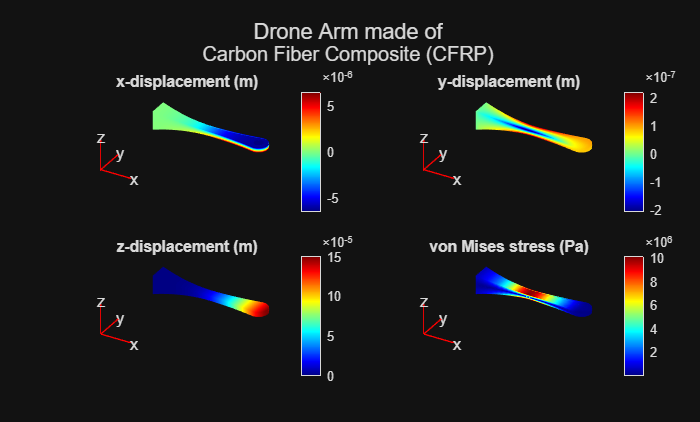

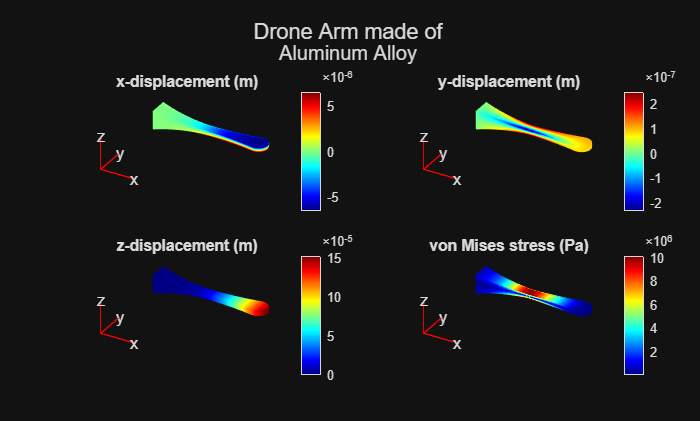

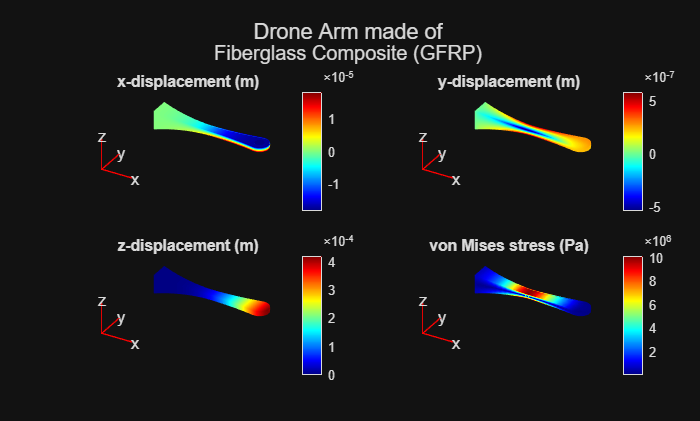

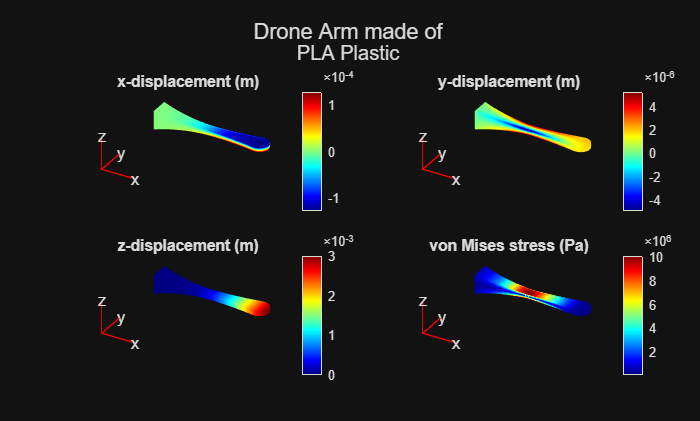

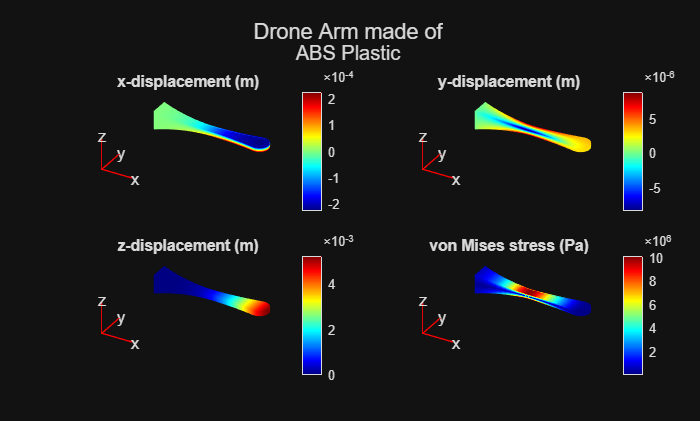

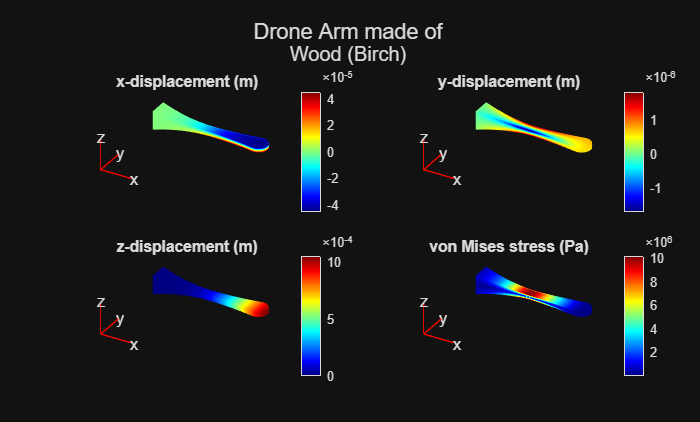

resultsTable = 6×6 table
          Drone Arm Material           Mass of Drone Arm (kg)    Yield Strength (Pa)    Von Mises Strength (Pa)    Maximum Displacement (µm)    Factor of Safety
    _______________________________    ______________________    ___________________    _______________________    _________________________    ________________

    "Carbon Fiber Composite (CFRP)"           0.020731                   6e+08                1.0137e+07                    150.24                   59.188     
    "Aluminum Alloy"                          0.034984                2.75e+08                1.0132e+07                    152.33                   27.141     
    "Fiberglass Composite (GFRP)"             0.024618                   3e+08                 1.014e+07                    42

% The Finite Element Analysis (FEA) is run in 3 scripts, one for each arm
% Drone Arm A -> EPPDronePayloadTeam7\FiniteElementAnalysisArmA.m
% Drone Arm B -> EPPDronePayloadTeam7\FiniteElementAnalysisArmA.m
% Drone Arm C -> EPPDronePayloadTeam7\FiniteElementAnalysisArmA.m

run 'FiniteElementAnalysisArmA.m' % Runs the Arm A FEA

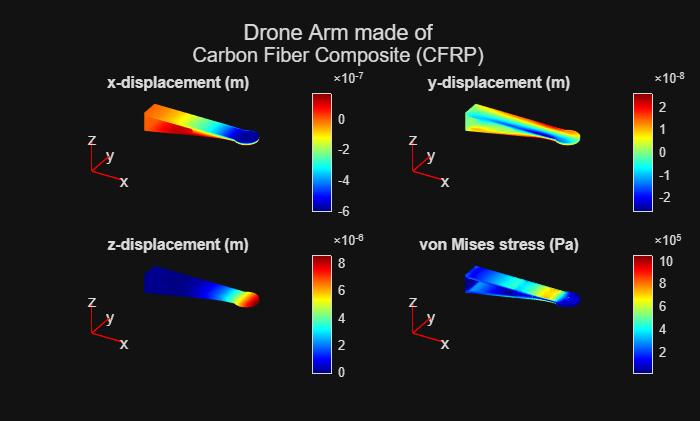

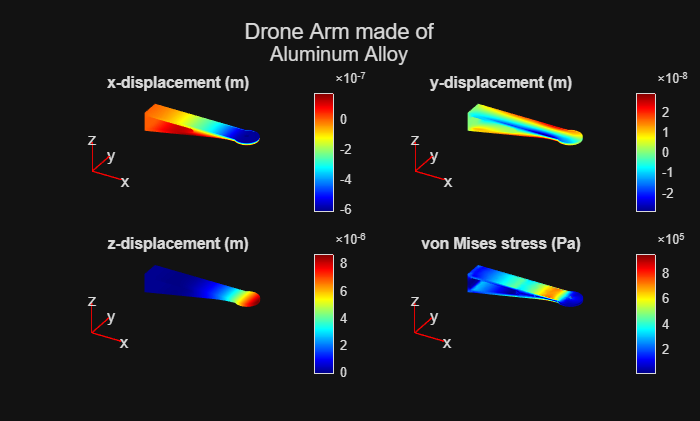

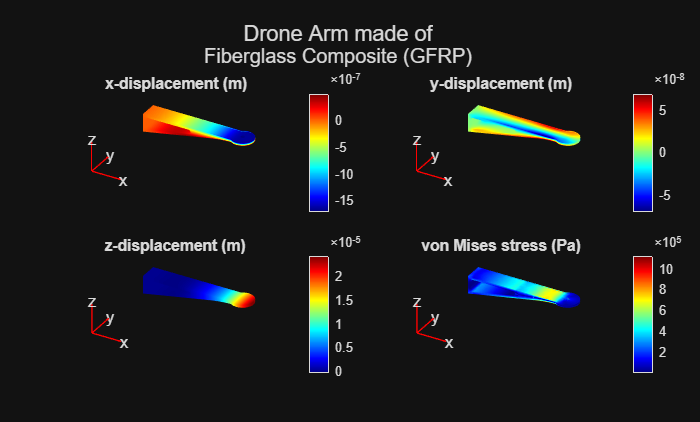

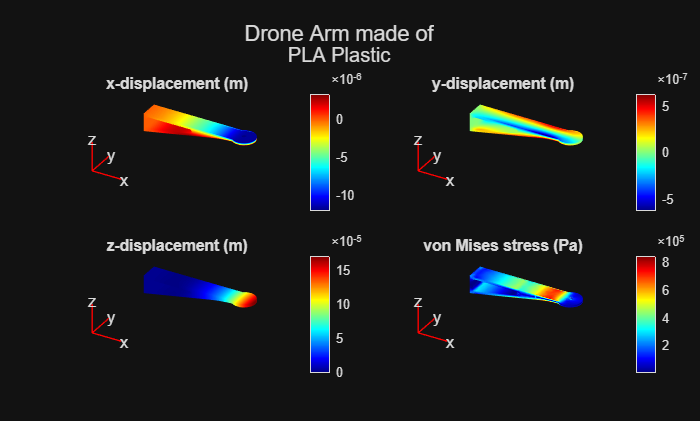

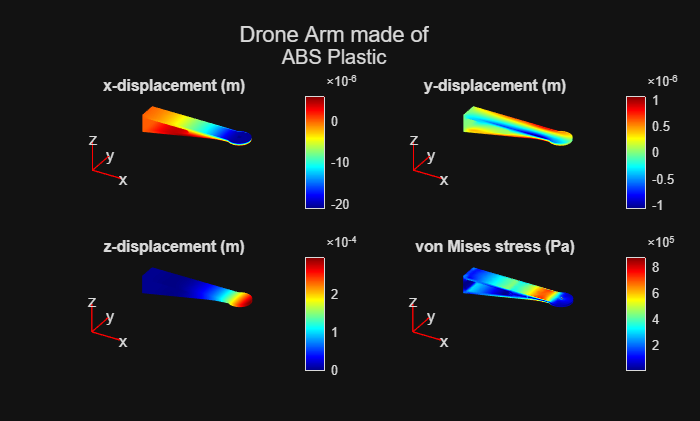

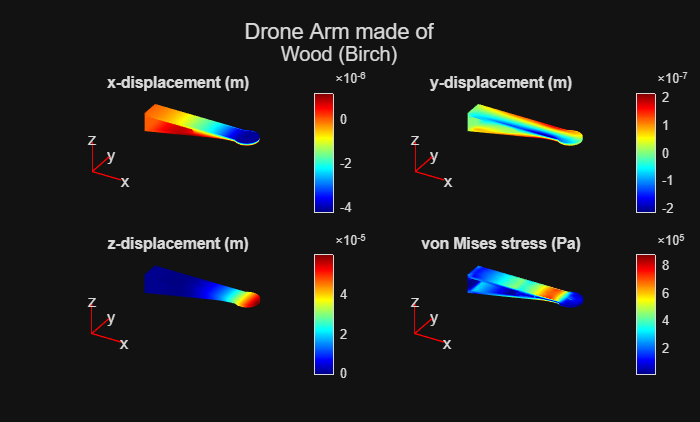

resultsTable = 6×6 table
          Drone Arm Material           Mass of Drone Arm (kg)    Yield Strength (Pa)    Von Mises Strength (Pa)    Maximum Displacement (µm)    Factor of Safety
    _______________________________    ______________________    ___________________    _______________________    _________________________    ________________

    "Carbon Fiber Composite (CFRP)"           0.022461                   6e+08                1.0503e+06                    8.5906                   571.27     
    "Aluminum Alloy"                          0.037903                2.75e+08                9.4879e+05                    8.7052                   289.84     
    "Fiberglass Composite (GFRP)"             0.026672                   3e+08                1.1145e+06                     2

clear
run 'FiniteElementAnalysisArmB.m' % Runs the Arm B FEA

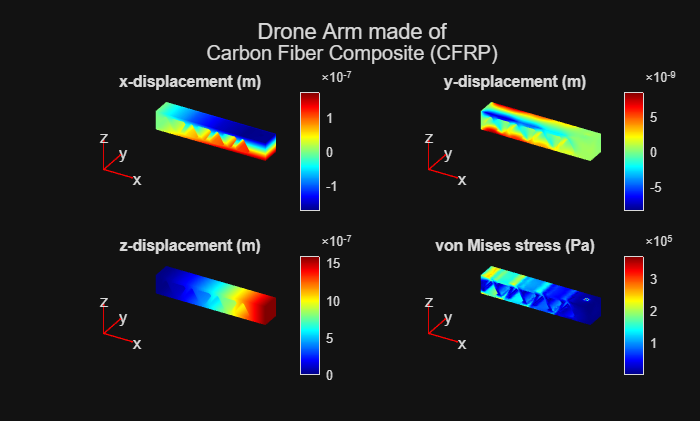

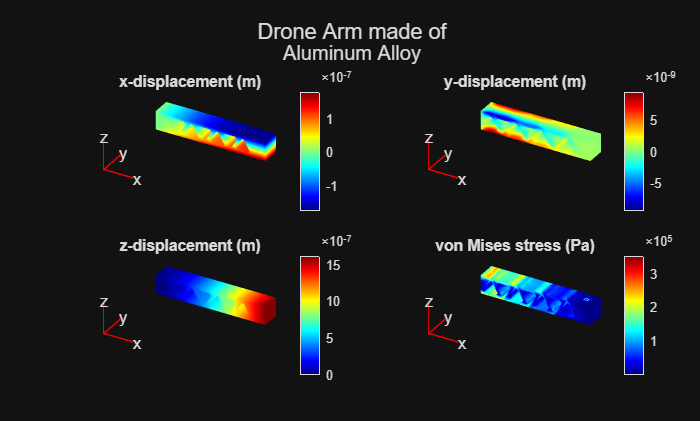

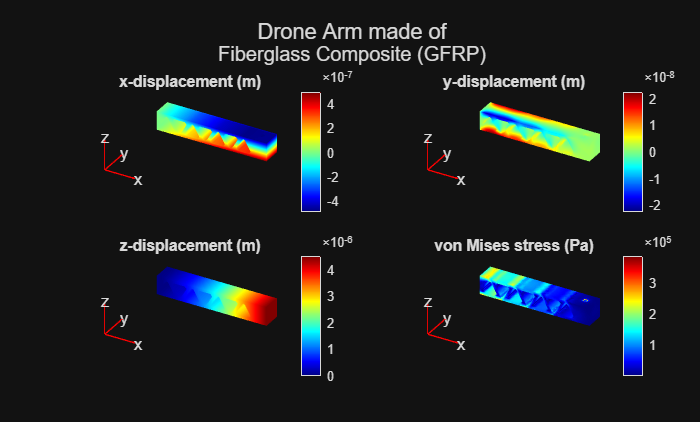

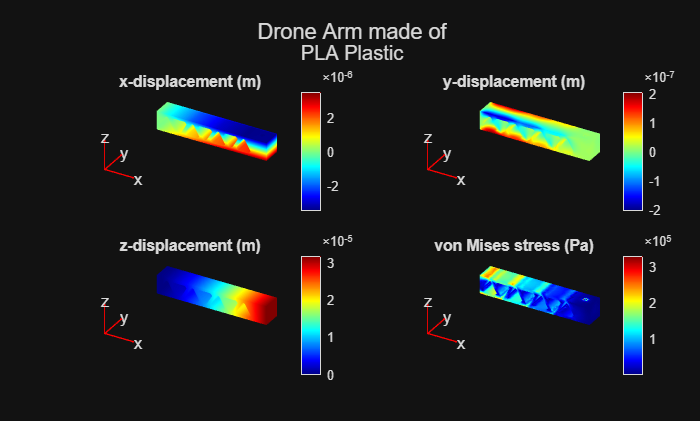

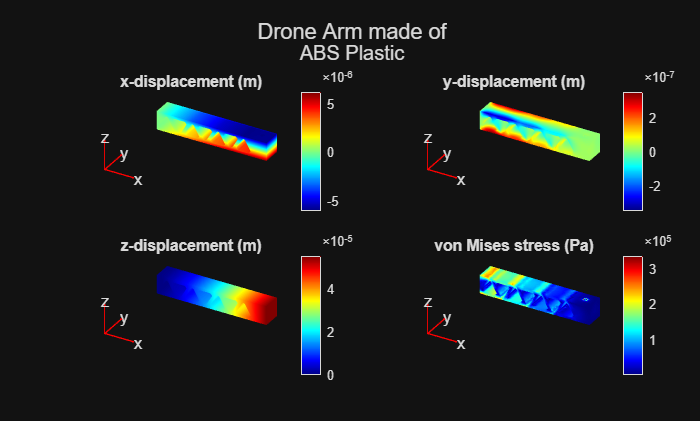

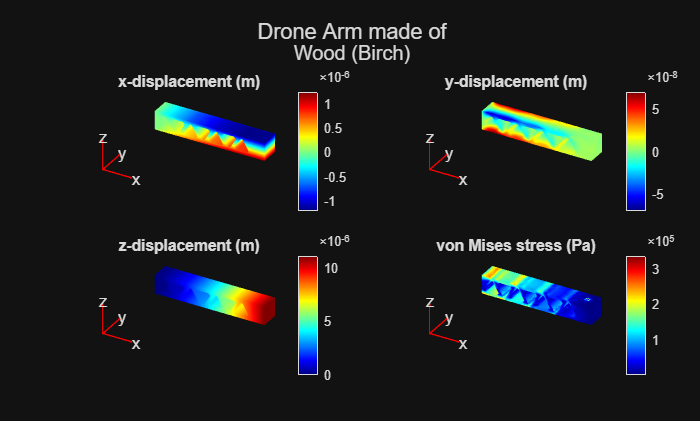

resultsTable = 6×6 table
          Drone Arm Material           Mass of Drone Arm (kg)    Yield Strength (Pa)    Von Mises Strength (Pa)    Maximum Displacement (µm)    Factor of Safety
    _______________________________    ______________________    ___________________    _______________________    _________________________    ________________

    "Carbon Fiber Composite (CFRP)"           0.046068                   6e+08                3.7374e+05                    1.6094                   1605.4     
    "Aluminum Alloy"                           0.07774                2.75e+08                3.5234e+05                    1.6267                   780.49     
    "Fiberglass Composite (GFRP)"             0.054706                   3e+08                3.8724e+05                    4.

clear
run 'FiniteElementAnalysisArmC.m' % Runs the Arm C FEA

clear

% The results can also be viewed in the folder 
% 'EPPDronePayloadTeam7\FEA Results\'


## Interpretation of Results - Final Recommended Design Solution

Using the results of your thrust-to-weight analysis and finite element analysis, recommend a final drone arm design that meets all required constraints. Your recommendation should clearly identify the selected design (arm geometry and material choice), make use of quantitative results to justify your decisions, demonstrate that the design meets the constraints, explain the trade-offs considered, and include comparisons to alternative designs.

What are some limitations of your work?

The drone arm masses have some error due to being calculated based upon the volume of the STL models. Due to STL files being a triangular mesh, they are not based upon actual geometry which can introduce error, especially with more complex models like arms B and C.

The finite element analysis only account for the forces of the motor and gravity, and does not take into account other important factors, such as repeated loads on the material. The results would likely be significantly different if the drone arm designs needed to be impact resistant, as plywood is not very durable.

What are practical next steps?